%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent-substrate mismatch position on DNA/RNA
%toehold exchange kinetics including spontaneous incumbent dissociation


b = 20 %define branch migration domain length

b =     20


g = 4 %define invader toehold length

g =      4


g2 = 1 %define incumbent toehold length 

g2 =      1



bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 =     21



R = 1.987/1000 %universal gas constant in kcal/K/mol 

R =    0.001987000000000


temp = 298.15 %temperature in K

temp =      2.981500000000000e+02


%free energy parameters
dGassoc = 2.6*R*temp

dGassoc =    1.540302530000000


dGbp = -2.52*R*temp

dGbp =   -1.492908606000000


dGp = 3.6*R*temp

dGp =    2.132726580000000


dGrd = -0*R*temp

dGrd =      0


dGbm = 7.4*R*temp

dGbm =    4.383937970000000


%absolute rate constant
k_bp = 5.4*10^7

k_bp =     54000000


k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:20
    m
    
    %loop through states prior to mismatch (in branch migration domain) and
    %define free energy
    for state = 1:m-1
        dGbox_avr(m, state) = - R*temp*log(exp(-((-dGbp-dGrd)*(m - state) + (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm+(m-state)*(dGrd) + (m)*-dGrd + dGp)/(R*temp))) 
    end
    
    %define free energy to states after mismatch (in branch migration
    %domain)
    dGbox_avr(m, 1:m) = horzcat(dGbox_avr(m, 1:m-1), dGp - (m)*dGrd)

    %define free energy to final state in invader toehold 
    dGboxC1 = -R*temp*log(exp(-((-dGbp - dGrd)*(m-0) + (m)*-dGrd + dGp)/(R*temp)) + exp(-(dGmm)/(R*temp)))
    
    trans_state = (-dGbp - dGrd)*(b +g2-1)
    react_coord = zeros(1, b-1)
    %loop through states prior to mismatch and define free energy (in terms
    %of incumbent dissociation)
    for state = 1:m-1
        react_coord(state) = -R*temp*log(exp(-(state*(-dGbp-dGrd) + dGmm)/(R*temp)) + exp(-(state*(-dGbp-dGrd))/(R*temp)))
    end
    %loop through states after mismatch and define free energy (in terms of
    %incumbent dissociation)
    for state = m:b-1
        react_coord(state) = state*(-dGbp-dGrd)
    end
    react_coord = flip(react_coord);
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_C1fm = k_bp * exp(-(dGbox_avr(m,1) - dGboxC1 + dGbm)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))

    k_Cfbm = zeros(1, m-2)
    for state = 2:m 
        k_Cfbm(state - 1) = k_bp * exp(-(dGbox_avr(m, state) - dGbox_avr(m, state - 1) + dGbm)/(R*temp))
    end
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp *exp((dGbp + dGrd)/(R*temp))
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates for mismatch-free
    %system
    Koff_perf = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff_perf = horzcat(Koff_perf, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
    end
    Koff_perf = horzcat(Koff_perf, [repmat(0, [1, g+1])])
    
    if g == 1
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-m]), flip(k_Cfbm), k_C1f, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
        %define spontaneous incumbent dissociation rates for mismatch system
        Koff = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0, 0])
        
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-m]), flip(k_Cfbm), k_C1fm, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [repmat(0, [1, g2+1])]; 
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp - dGrd)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff_perf(Pn) * Pn_jN_1_perf(Pn);
    end
        
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %probability of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8)); %effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%probability of being in unbound state for mismatch-free system
end

m =      1


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    3.605800432260688


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492908606000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      3.967310741986029e+05


k_Cf =      3.300764910099690e+04



k_Cfbm =

  1×0 empty double row vector



k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf = 	1.0e+05 *

                   0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.039673107419860   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb = 	1.0e+06 *

                   0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff = 	1.0e+05 *

                   0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf = 	1.0e+02 *

   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      2


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    4.909488473760101


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      2.885268017052751e+05


k_Cf =      3.300764910099690e+04



k_Cfbm =

  1×0 empty double row vector



k_Cfbm =      4.098574657759203e+05


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.028852680170528   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      3


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.524905167117471


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      6.629836692102291e+04


k_Cf =      3.300764910099690e+04


k_Cfbm =      0


k_Cfbm =      4.059269292946876e+05


k_Cfbm =    4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.006629836692102   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      4


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.619033898885303


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      7.069775563334969e+03


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0


k_Cfbm =    3.628404773093044                   0


k_Cfbm =    3.628404773093044   4.059269292946876


k_Cfbm =    3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.000706977556333   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      5


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.627299701621379


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      1.405130020937113e+03


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0


k_Cfbm =    1.684081892459625                   0                   0


k_Cfbm =    1.684081892459625   3.628404773093044                   0


k_Cfbm =    1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.000140513002094   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      6


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.627969805004818


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.424280139972576e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0


k_Cfbm =    4.926904666199513                   0                   0                   0


k_Cfbm =    0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.000094242801400   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      7


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628023754220313


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.051536641020269e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0


k_Cfbm =    3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.000090515366410   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233  39.629381252180572                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      8


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028095166530


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.021542894657645e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0


k_Cfbm =    3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.000090215428947   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233  39.629381252180572  52.138246054971155                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =      9


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028444438740


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.019129590514320e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0


k_Cfbm =    3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.000090191295905   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233  39.629381252180572  52.138246054971155  64.650741967216618                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     10


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028472541053


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018935416888299e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0


k_Cfbm =    3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.000090189354169   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233  39.629381252180572  52.138246054971155  64.650741967216618  77.163592608660721                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     11


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474802154


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018919793753897e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.000090189197938   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    5.950247558653351   5.520880354322463   5.628866238173444   7.194132538738392  15.200430195703451  27.163760648279233  39.629381252180572  52.138246054971155  64.650741967216618  77.163592608660721  89.676528050452092                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0


m =     12


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474984081


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918536722649e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.000090189185367   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0


m =     13


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474998719


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918435582410e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.000090189184356   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0


m =     14


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999897


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918427444702e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.000090189184274   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0


m =     15


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999992


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426789962e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.000090189184268   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492                   0                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0


m =     16


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999999


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426737254e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910119022                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.003300764910119   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492   1.522421296263459                   0                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451   0.999893517241682                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0


m =     17


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426733023e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910101245                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.003300764910119   0.003300764910101   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492   1.522421296263459   1.647554545130812                   0                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451   0.999893517241682   0.999892578650018                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0


m =     18


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426732704e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910099811                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.003300764910119   0.003300764910101   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492   1.522421296263459   1.647554545130812   1.772688934889977                   0                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451   0.999893517241682   0.999892578650018   0.999891429193989                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0


m =     19


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910099705                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.003300764910119   0.003300764910101   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281251579502522   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492   1.522421296263459   1.647554545130812   1.772688934889977   1.897820610427342                   0


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451   0.999893517241682   0.999892578650018   0.999891429193989   0.999890134381503                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0


m =     20


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324  28.365219171635321


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1fm =      9.018918426732656e+02


k_Cf =      3.300764910099690e+04


k_Cfbm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_Cfbm =    3.300764910099690                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207                   0                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640                   0                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231                   0                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223                   0                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049                   0                   0                   0                   0


k_Cfbm =    3.300764910099690   3.300764910099705   3.300764910099811   3.300764910101245   3.300764910119022   3.300764910339847   3.300764913084513   3.300764947196788   3.300765371164558   3.300770640488207   3.300836130663640   3.301650062664231   3.311763164953223   3.437003831210049   4.926904666199513                   0                   0                   0


k_Cfbm =    0.330076491009969   0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625                   0                   0


k_Cfbm =    0.330076491009969   0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044                   0


k_Cfbm =    0.330076491009969   0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876


k_Cfbm =    0.330076491009969   0.330076491009970   0.330076491009981   0.330076491010124   0.330076491011902   0.330076491033985   0.330076491308451   0.330076494719679   0.330076537116456   0.330077064048821   0.330083613066364   0.330165006266423   0.331176316495322   0.343700383121005   0.492690466619951   1.684081892459625   3.628404773093044   4.059269292946876   4.098574657759203


k_DC =      9.018918426732656e+02


k_EF =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.040985746577592   0.040592692929469   0.036284047730930   0.016840818924596   0.004926904666200   0.003437003831210   0.003311763164953   0.003301650062664   0.003300836130664   0.003300770640488   0.003300765371165   0.003300764947197   0.003300764913085   0.003300764910340   0.003300764910119   0.003300764910101   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495562442630944   0.281251579502522   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.059502475586534   0.055208803543225   0.056288662381734   0.071941325387384   0.152004301957035   0.271637606482792   0.396293812521806   0.521382460549712   0.646507419672166   0.771635926086607   0.896765280504521   1.021895260726417   1.147025848538481   1.272157043021681   1.397288848616492   1.522421296263459   1.647554545130812   1.772688934889977   1.897820610427342   2.022876819405283


prob_unbound =    0.999177196272619   0.999208358262564   0.999309242034289   0.999503225493946   0.999742524592503   0.999827590365423   0.999859708892858   0.999875322276338   0.999883957912150   0.999889007901736   0.999891973064081   0.999893619236856   0.999894378081195   0.999894511401571   0.999894187084451   0.999893517241682   0.999892578650018   0.999891429193989   0.999890134381503   0.999888784395127


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798


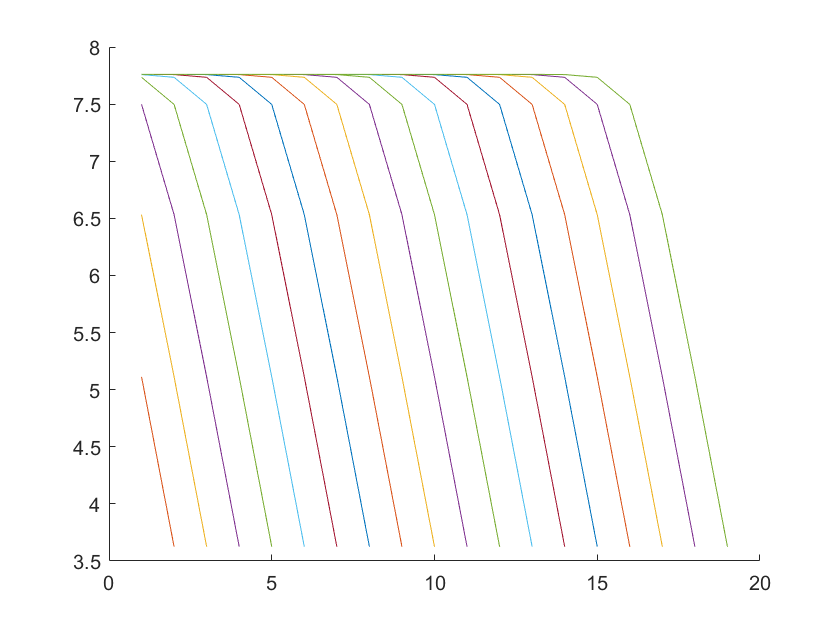

for m = 1:20
    plot(1:m-1, dGbox_avr(m, 1:m-1))
    hold on
end
hold off 

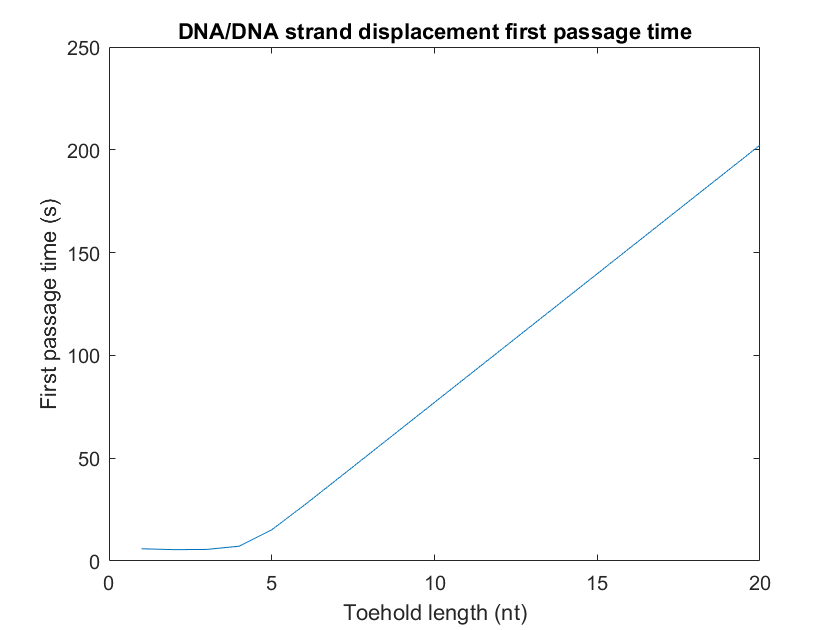


plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

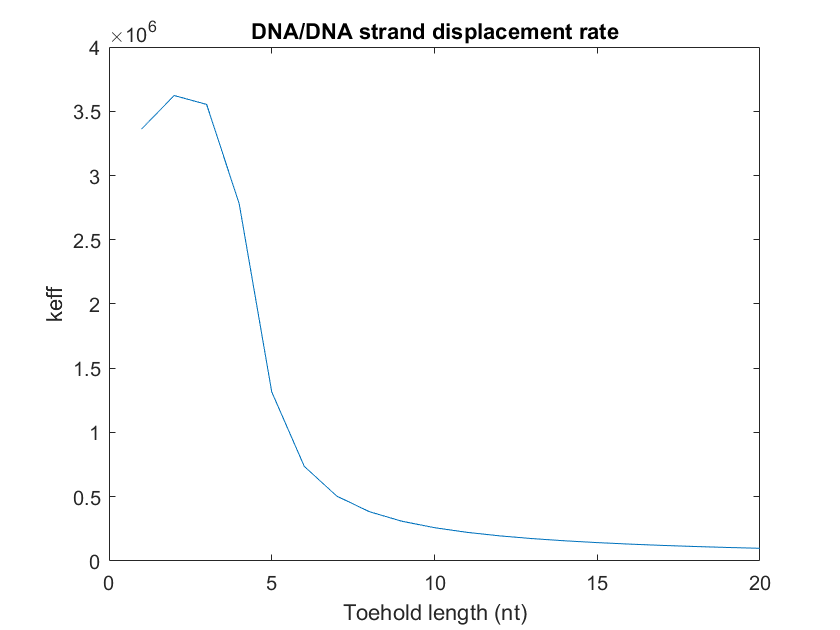


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

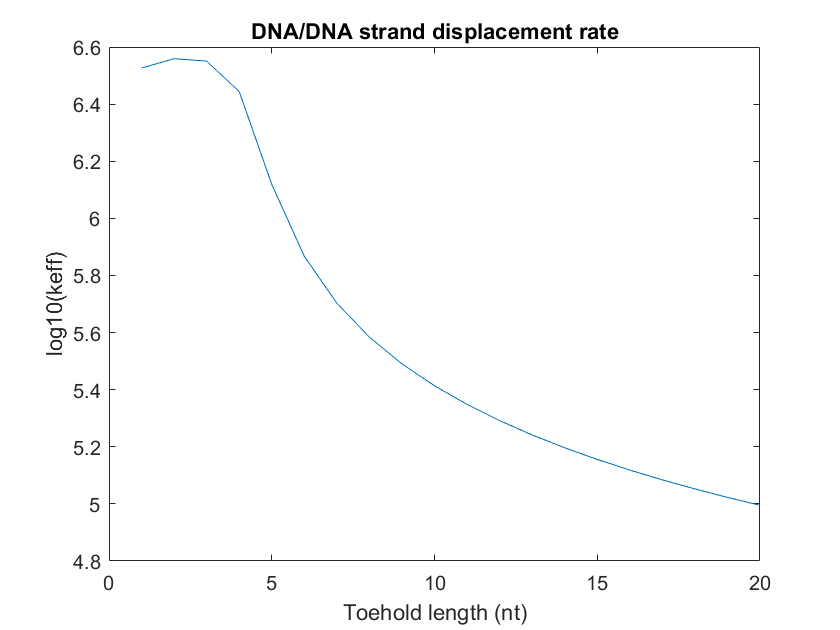


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  

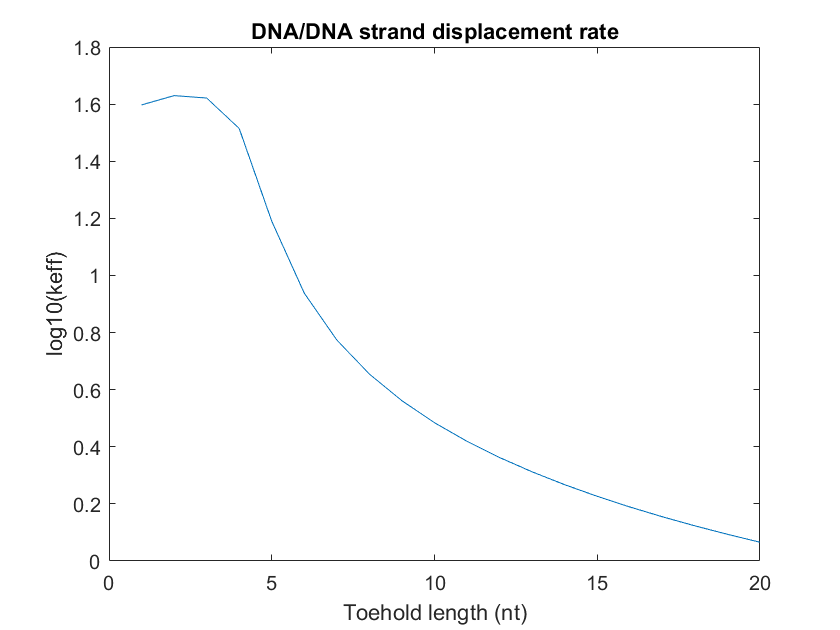


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  